# SSB_main

## 定义参数

T = 0.3;
dt = 0.001;%时间微元
fs = 1/dt;
N = T/dt;%总计离散处理的点数
t = (0:N-1)*dt;%时间轴
fc = 100;%载波频率
fm = 25;
am = 2;

## 调制

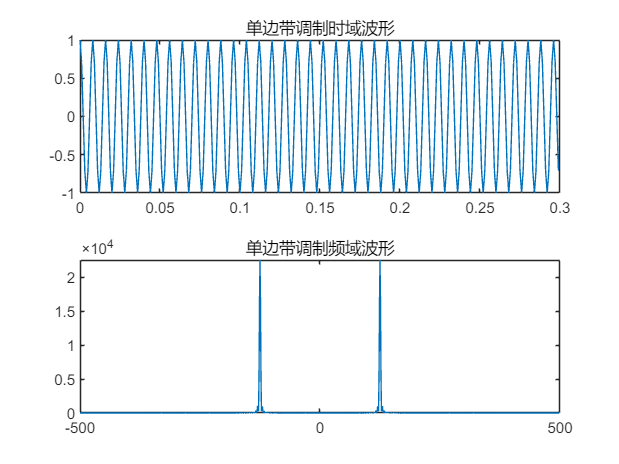

SSB=SSB_modulation(t,fc,fm,am);
[freq1,spectrum1] = analyze_spectrum(SSB,fs,1000);
figure(1);
subplot(2,1,1);plot(t,SSB);title('单边带调制时域波形');
subplot(2,1,2);plot(freq1,spectrum1);title('单边带调制频域波形');

## 通过信道

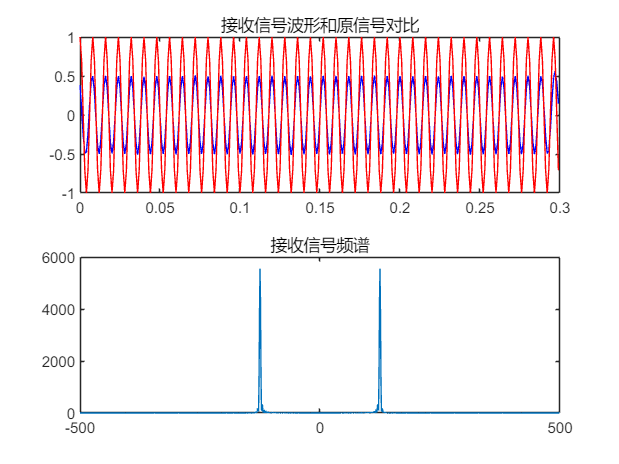

f_c = fc + fm;  % f_c是截止频率，为SSB调制进行调整
received_signal = channel_simulation(SSB, 40, f_c, fs);
[freq2,spectrum2]=analyze_spectrum(received_signal,fs,1000);
% 图2：接收到的信号的波形和频谱
figure(2);
subplot(2,1,1);plot(t,received_signal,'b');hold on;plot(t,SSB,'r');hold off;title('接收信号波形和原信号对比');
subplot(2,1,2);plot(freq2,spectrum2);title('接收信号频谱');

## 解调

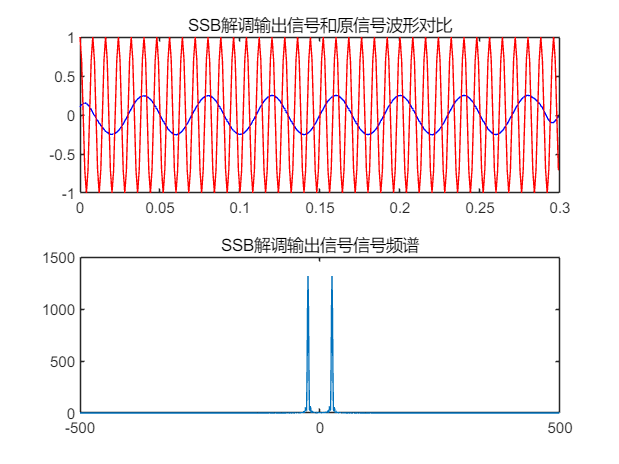

[m_t,mix_t] = Coherent_Demodulation(received_signal,t,fc,fs);
[freq3,spectrum3]=analyze_spectrum(m_t,fs,1000);
% 图3：
figure(3);
subplot(2,1,1);plot(t,m_t,'b');hold on;plot(t,SSB,'r');hold off;title('SSB解调输出信号和原信号波形对比');
subplot(2,1,2);plot(freq3,spectrum3);title('SSB解调输出信号信号频谱');